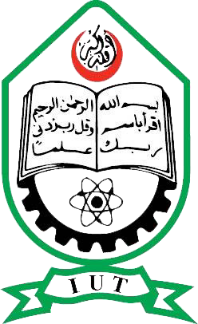

Islamic University of Technology

Name                          : Ahnaf Sakif

Student ID                   : 220021127 

Section                        : A-(01) 

Department                 :EEE 

Course No                    : EEE-4416

Course Title                 : Matlab Simulation Lab

Experiment No            : 9

Date of Submission    : 17/08/2025

## Exercises:

### Exercise - 01:


summary(cirrhosis);

Variables:

    N_Days: 418×1 double

        Values:

            Min           41  
            Median      1730  
            Max         4795  

    Status: 418×1 double

        Values:

            Min          0    
            Median       0    
            Max          2    

    Drug: 418×1 double

        Values:

            Min          0    
            Median       1    
            Max          2    

    Age: 418×1 double

        Values:

            Min         9598  
            Median     18628  
            Max        28650  

    Sex: 418×1 double

        Values:

            Min          0    
            Median       0    
            Max          1    

    Ascites: 418×1 double

        Values:

            Min          0    
            Median       0    
            Max          2    

    Hepatomegaly: 418×1 double

        Values:

     

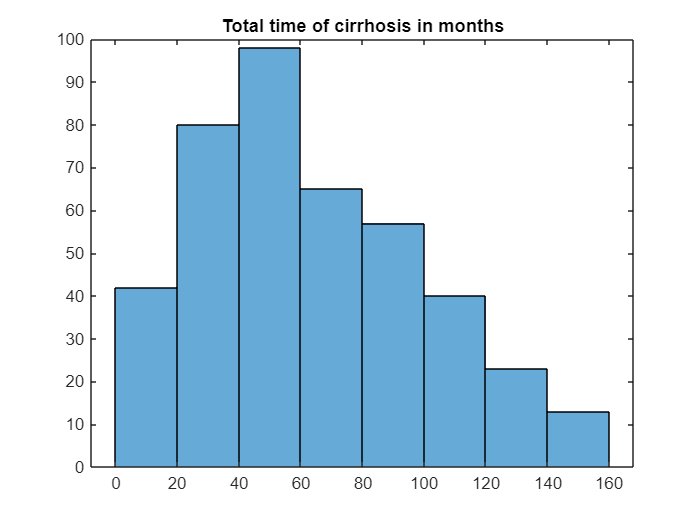


histogram(cirrhosis.N_Days/30);
title('Total time of cirrhosis in months');

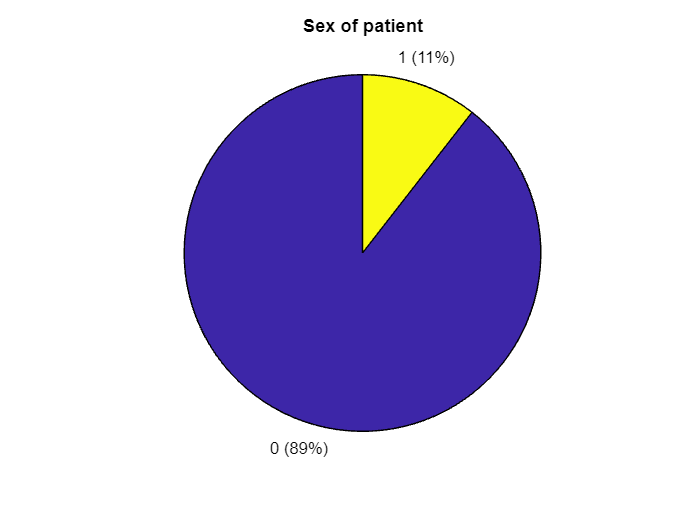


pie(categorical(cirrhosis.Sex));
title('Sex of patient');

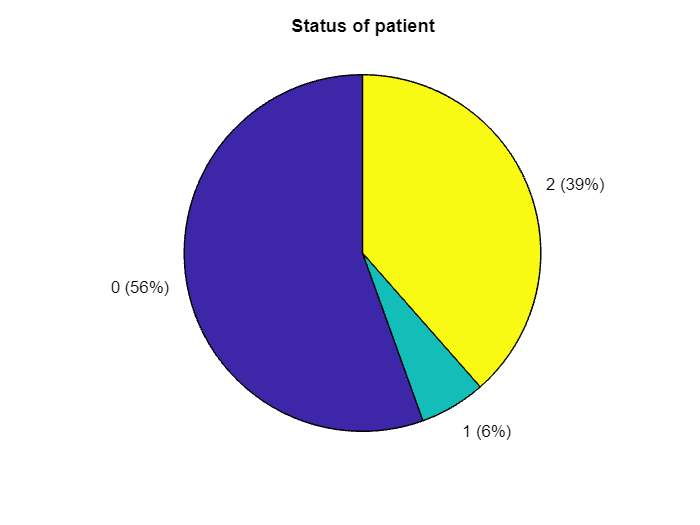


pie(categorical(cirrhosis.Status));
title('Status of patient');

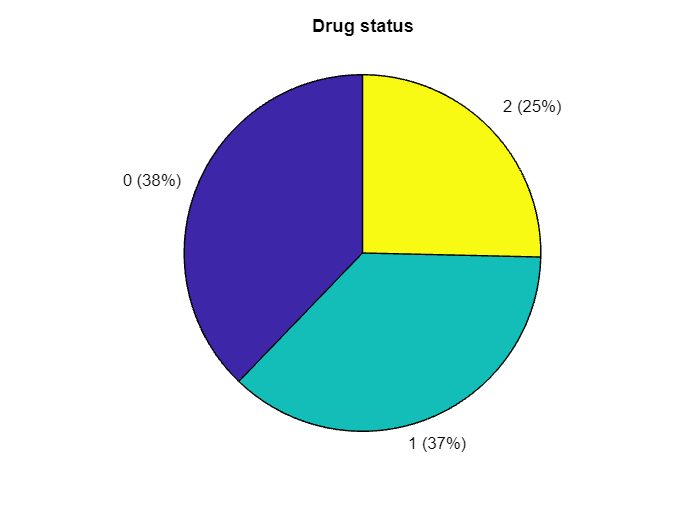


pie(categorical(cirrhosis.Drug));
title('Drug status');

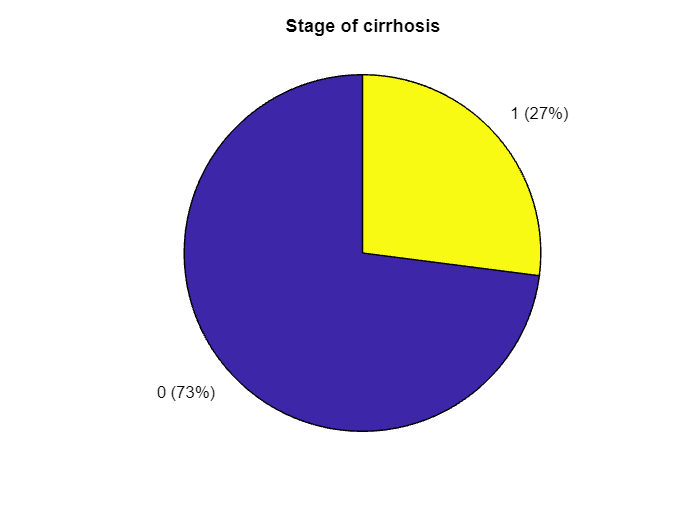


pie(categorical(cirrhosis.Stage));
title('Stage of cirrhosis');

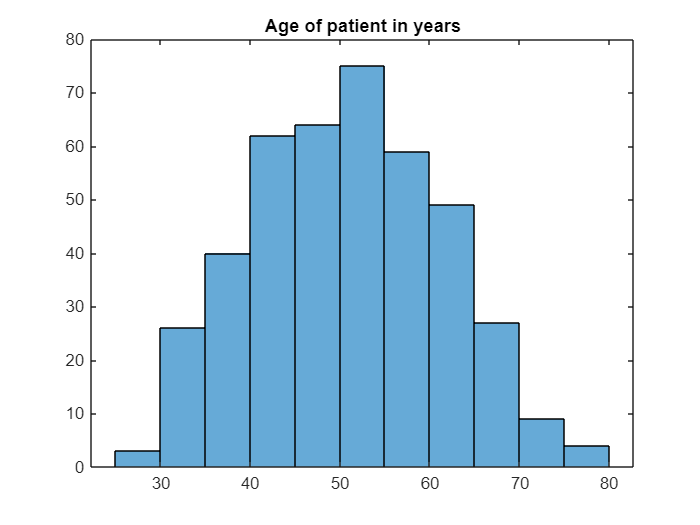


histogram(cirrhosis.Age/365);
title('Age of patient in years');

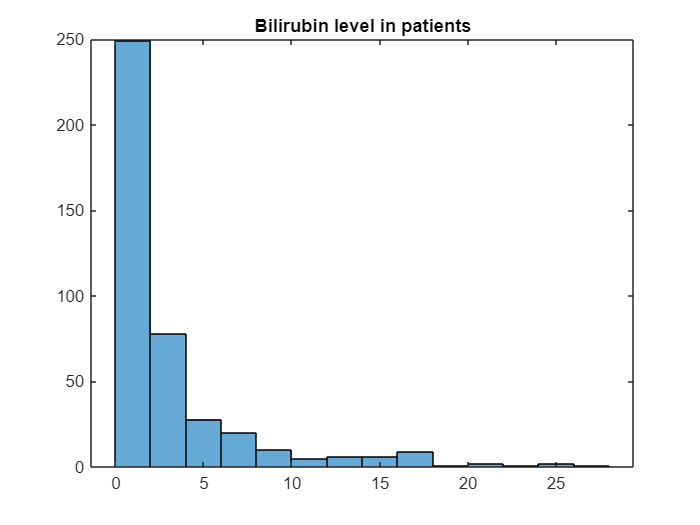


histogram(cirrhosis.Bilirubin);
title('Bilirubin level in patients');

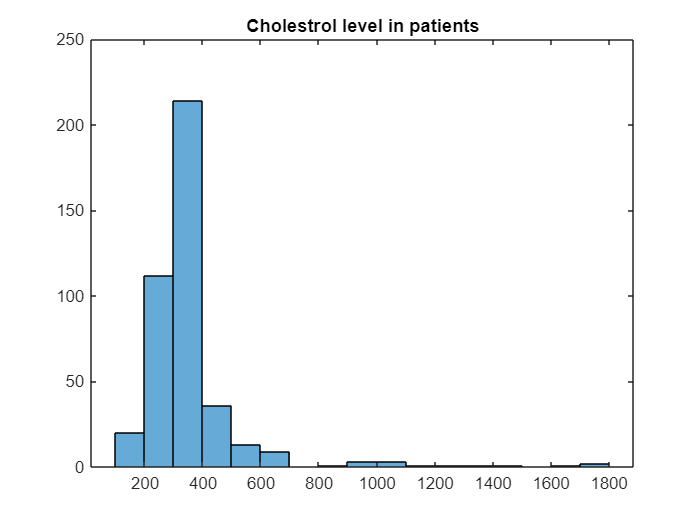


histogram(cirrhosis.Cholesterol);
title('Cholestrol level in patients');

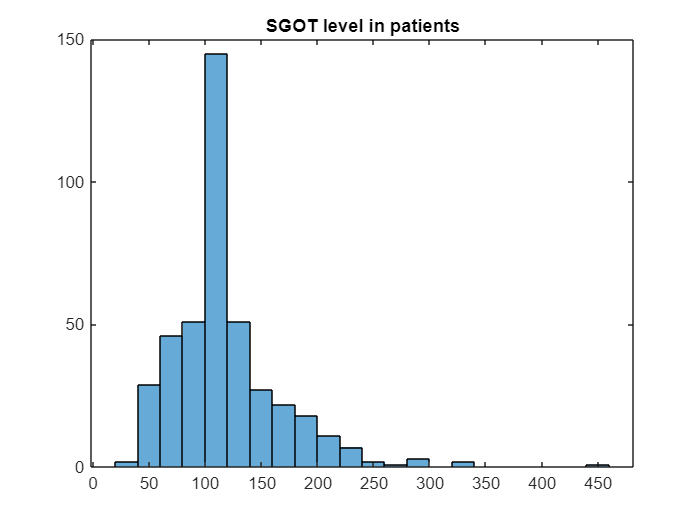


histogram(cirrhosis.SGOT);
title('SGOT level in patients');

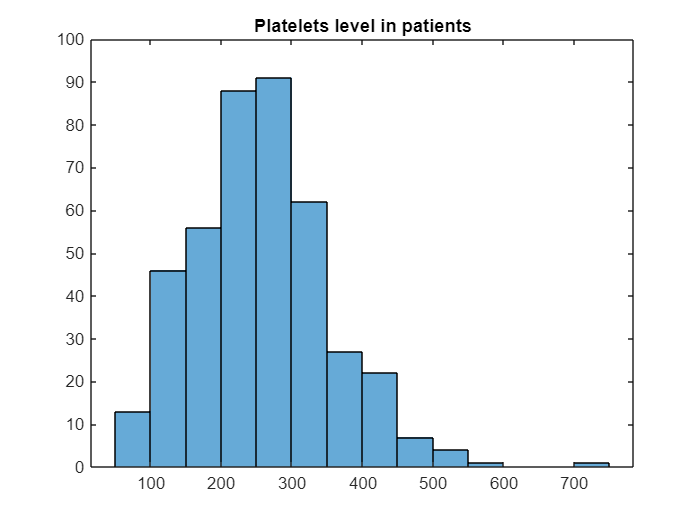


histogram(cirrhosis.Platelets);
title('Platelets level in patients');

### Exercise - 02

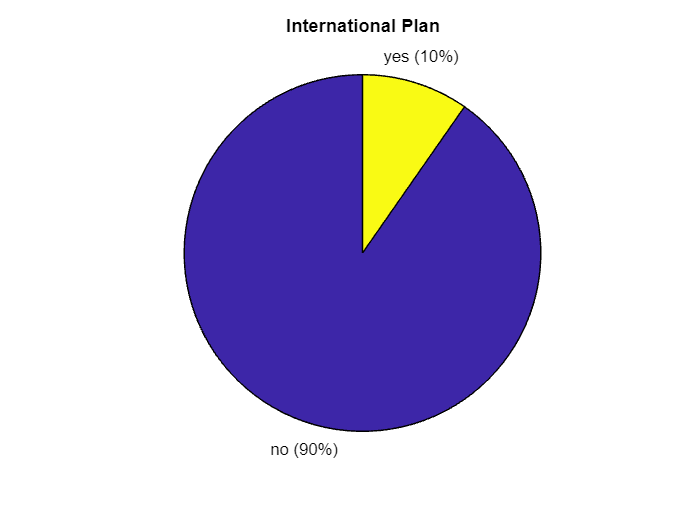


pie(BigMLDataset.internationalPlan);
title('International Plan');

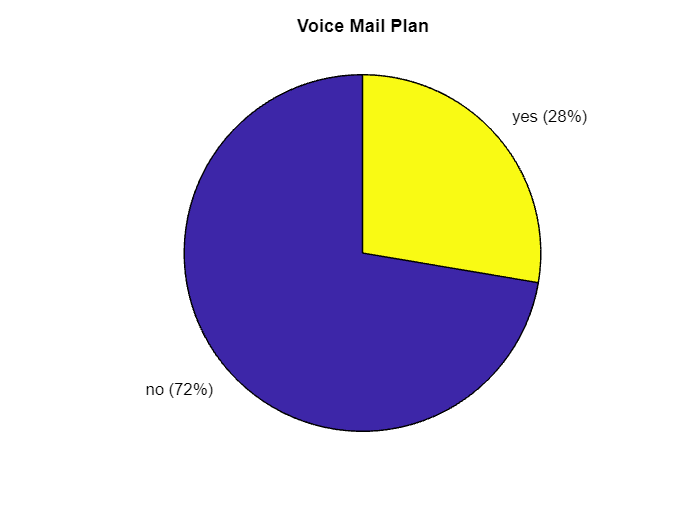


pie(BigMLDataset.voiceMailPlan);
title('Voice Mail Plan');

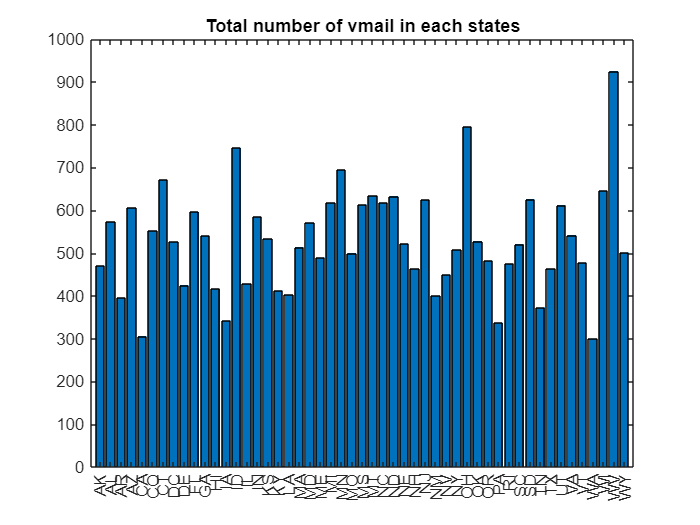


vmail = groupsummary(BigMLDataset, "state", "sum", "numberVmailMessages");
bar(vmail{:,1},vmail{:,3});
title("Total number of vmail in each states");

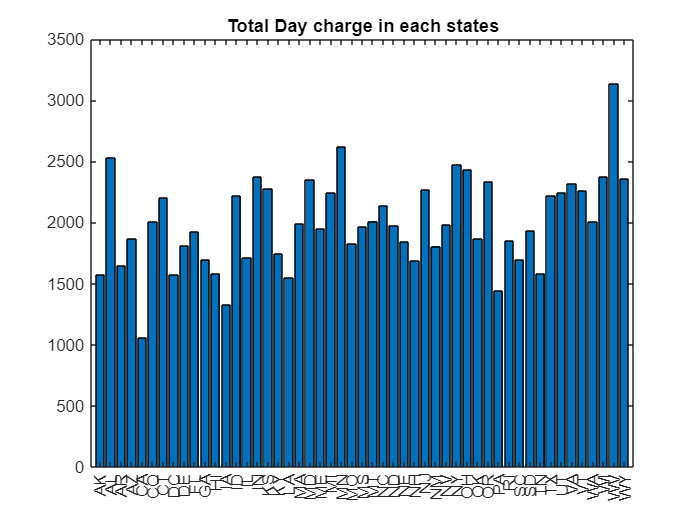


daycharge = groupsummary(BigMLDataset, "state", "sum", "totalDayCharge");
bar(daycharge{:,1},daycharge{:,3});
title("Total Day charge in each states");

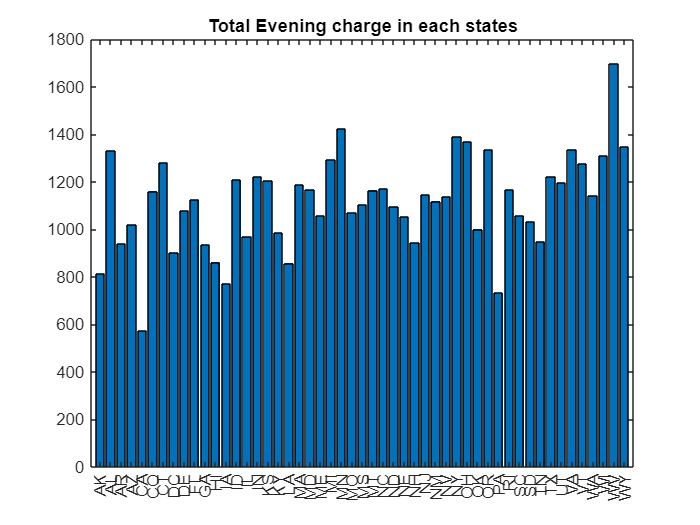


evecharge = groupsummary(BigMLDataset, "state", "sum", "totalEveCharge");
bar(evecharge{:,1},evecharge{:,3});
title("Total Evening charge in each states");

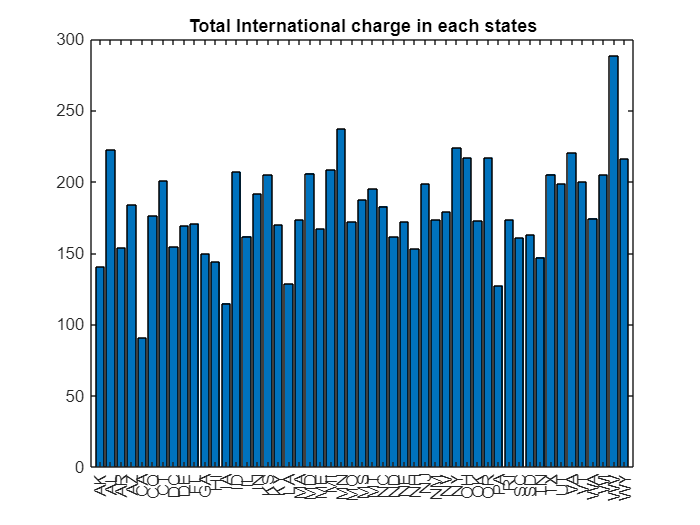


intlcharge = groupsummary(BigMLDataset, "state", "sum", "totalIntlCharge");
bar(intlcharge{:,1},intlcharge{:,3});
title("Total International charge in each states");

### Exercise - 03

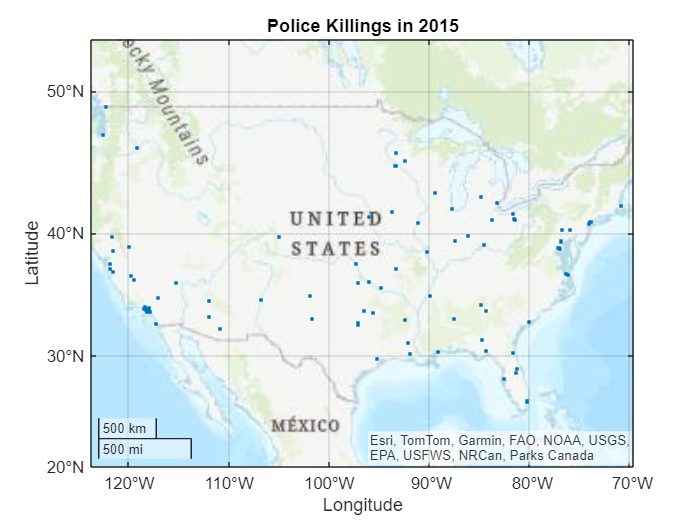

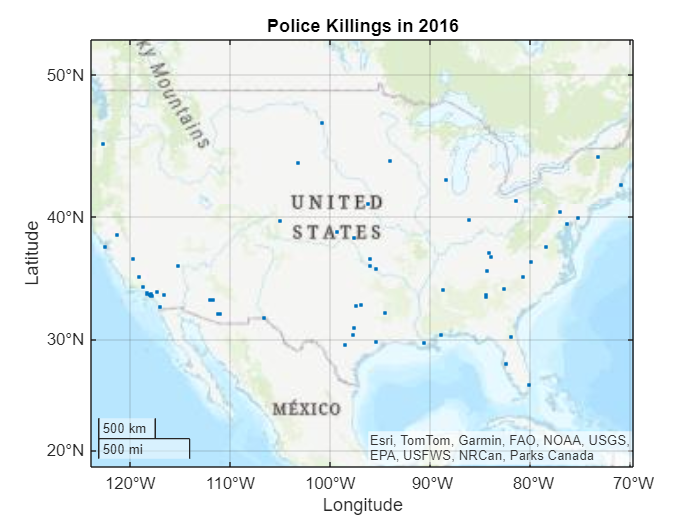

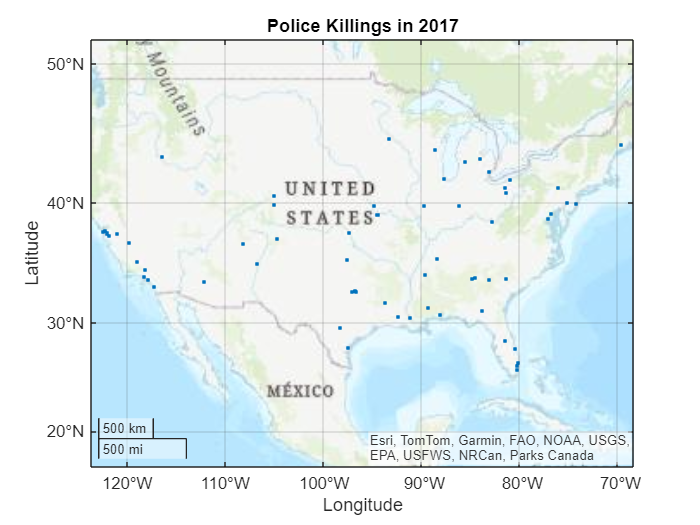

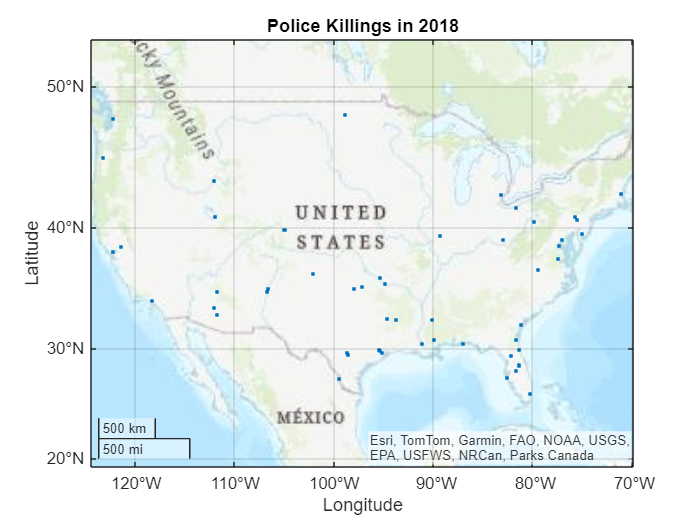

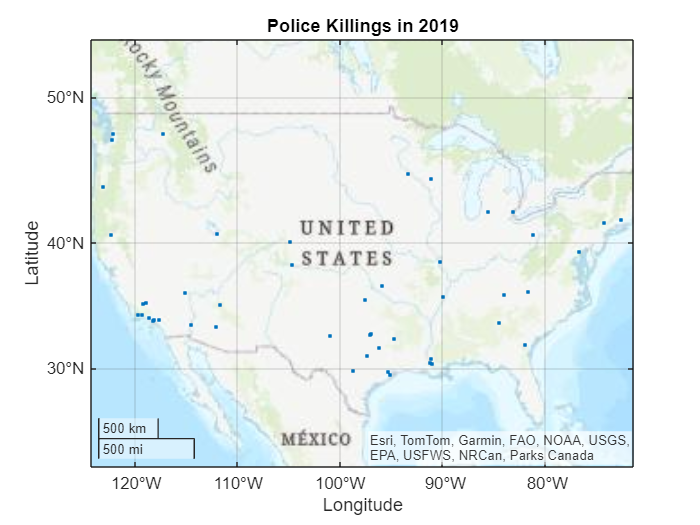

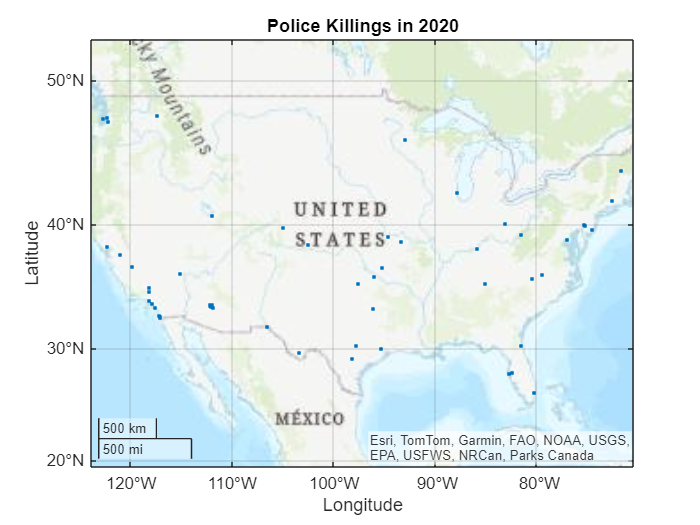

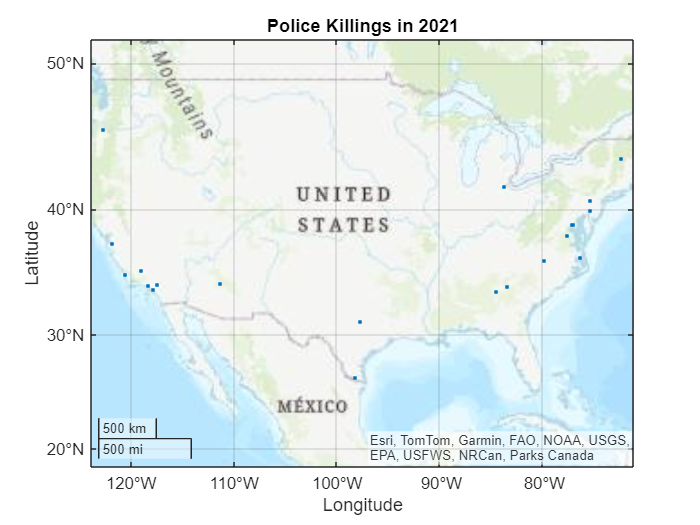

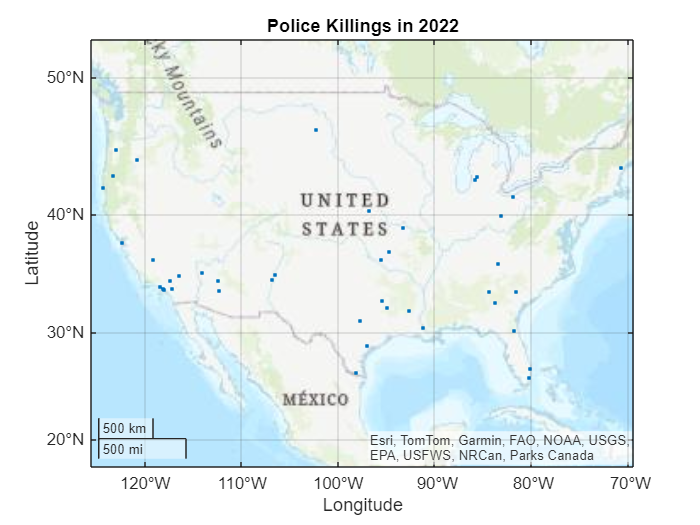


fatalpoliceshootingsdata.year = year(fatalpoliceshootingsdata.date);
unarmed_data = fatalpoliceshootingsdata(fatalpoliceshootingsdata.armed_with == 'unarmed', :);
lat_min = 24.396308;
lat_max = 49.384358;
lon_min = -125.0;
lon_max = -66.93457;
in_usa = (unarmed_data.latitude >= lat_min) & (unarmed_data.latitude <= lat_max) & (unarmed_data.longitude >= lon_min) & (unarmed_data.longitude <= lon_max);
df = unarmed_data(in_usa, :);
filename = 'unarmed police shootings.gif';
years = 2015:2022;
for i = 1:length(years)
    currentYear = years(i);
    subset = df(df.year == currentYear, :);
    figure;
    geoscatter(subset.latitude, subset.longitude, '.');
    geobasemap topographic
    title(sprintf('Police Killings in %d', currentYear));
    frame = getframe(gcf);
    im = frame2im(frame);
    [imind, cm] = rgb2ind(im, 256);
    if i == 1
        imwrite(imind, cm, filename, 'gif', 'Loopcount', inf, 'DelayTime', 1);
    else
        imwrite(imind, cm, filename, 'gif', 'WriteMode', 'append', 'DelayTime', 1);
    end
    pause(1);
end

**Exercise - 04:**

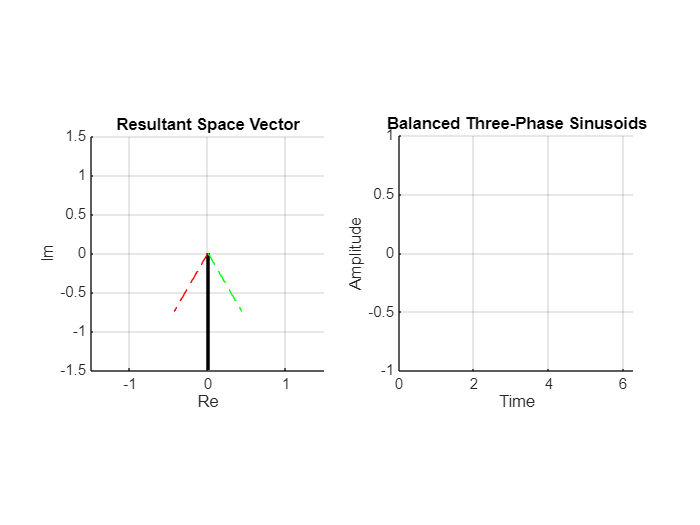

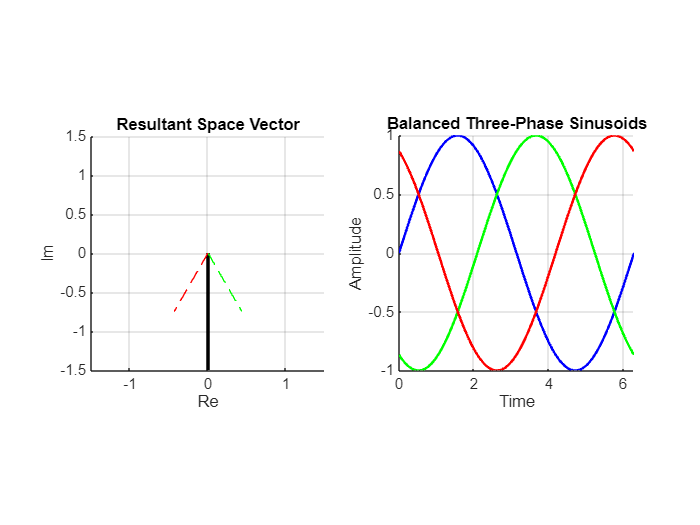

t = linspace(0, 2*pi, 300);
f = 1;
u = sin(t);
v = sin(t - 2*pi/3);
w = sin(t + 2*pi/3);
vec = u + v*exp(1j*2*pi/3) + w*exp(-1j*2*pi/3);
video = VideoWriter('Balanced Three Phase Sinusoids.mp4','MPEG-4'); 
video.FrameRate = 30;  
open(video);
figure('Color','w');
for k = 1:length(t)
    clf;
    subplot(1,2,1);
    hold on; 
    axis equal; 
    grid on;
    xlabel('Re'); 
    ylabel('Im');
    title('Resultant Space Vector');
    xlim([-1.5 1.5]); 
    ylim([-1.5 1.5]);
    plot([0 real(vec(k))],[0 imag(vec(k))],'k','LineWidth',2);
    plot([0 u(k)], [0 0],'b--');
    plot([0 v(k)*cos(2*pi/3)], [0 v(k)*sin(2*pi/3)],'g--');
    plot([0 w(k)*cos(-2*pi/3)], [0 w(k)*sin(-2*pi/3)],'r--');
    
    subplot(1,2,2);
    hold on; 
    grid on;
    xlabel('Time'); 
    ylabel('Amplitude');
    title('Balanced Three-Phase Sinusoids');
    xlim([0 max(t)]); 
    ylim([-1 1]);
    pbaspect([1 1 1])
    plot(t(1:k),u(1:k),'b','LineWidth',1.5);
    plot(t(1:k),v(1:k),'g','LineWidth',1.5);
    plot(t(1:k),w(1:k),'r','LineWidth',1.5);
    
    frame = getframe(gcf);
    writeVideo(video, frame);
end

close(video);


**Exercise - 05**

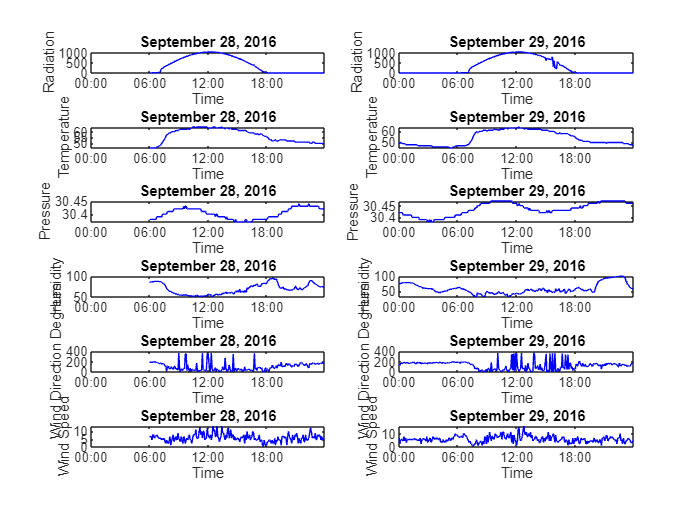

T29 = weatherdata(day(weatherdata.Data)==29,:);
T28 = weatherdata(day(weatherdata.Data)==28,:);
T29.Time = timeofday(T29.Time);
T28.Time = timeofday(T28.Time);

xmin = hours(timeofday(datetime('00:00:00','InputFormat','HH:mm:ss')));
xmax = hours(timeofday(datetime('23:59:59','InputFormat','HH:mm:ss')));
filename = 'Change_of_variables_with_time.gif';

for tDur = linspace(0,24,24)
    tHour = tDur;
    subplot(6,2,1)
    cla
    plot(hours(T28.Time(T28.Time<hours(tHour))),T28.Radiation(T28.Time<hours(tHour)),'b-')
    xlim([xmin xmax])
    xticks(0:6:24)
    xticklabels({'00:00','06:00','12:00','18:00','24:00'})
    title('September 28, 2016')
    xlabel('Time')
    ylabel('Radiation')

    subplot(6,2,2)
    cla
    plot(hours(T29.Time(T29.Time<hours(tHour))),T29.Radiation(T29.Time<hours(tHour)),'b-')
    xlim([xmin xmax])
    xticks(0:6:24)
    xticklabels({'00:00','06:00','12:00','18:00','24:00'})
    title('September 29, 2016')
    xlabel('Time')
    ylabel('Radiation')

    subplot(6,2,3)
    cla
    plot(hours(T28.Time(T28.Time<hours(tHour))),T28.Temperature(T28.Time<hours(tHour)),'b-')
    xlim([xmin xmax])
    xticks(0:6:24)
    xticklabels({'00:00','06:00','12:00','18:00','24:00'})
    title('September 28, 2016')
    xlabel('Time')
    ylabel('Temperature')

    subplot(6,2,4)
    cla
    plot(hours(T29.Time(T29.Time<hours(tHour))),T29.Temperature(T29.Time<hours(tHour)),'b-')
    xlim([xmin xmax])
    xticks(0:6:24)
    xticklabels({'00:00','06:00','12:00','18:00','24:00'})
    title('September 29, 2016')
    xlabel('Time')
    ylabel('Temperature')

    subplot(6,2,5)
    cla
    plot(hours(T28.Time(T28.Time<hours(tHour))),T28.Pressure(T28.Time<hours(tHour)),'b-')
    xlim([xmin xmax])
    xticks(0:6:24)
    xticklabels({'00:00','06:00','12:00','18:00','24:00'})
    title('September 28, 2016')
    xlabel('Time')
    ylabel('Pressure')

    subplot(6,2,6)
    cla
    plot(hours(T29.Time(T29.Time<hours(tHour))),T29.Pressure(T29.Time<hours(tHour)),'b-')
    xlim([xmin xmax])
    xticks(0:6:24)
    xticklabels({'00:00','06:00','12:00','18:00','24:00'})
    title('September 29, 2016')
    xlabel('Time')
    ylabel('Pressure')

    subplot(6,2,7)
    cla
    plot(hours(T28.Time(T28.Time<hours(tHour))),T28.Humidity(T28.Time<hours(tHour)),'b-')
    xlim([xmin xmax])
    xticks(0:6:24)
    xticklabels({'00:00','06:00','12:00','18:00','24:00'})
    title('September 28, 2016')
    xlabel('Time')
    ylabel('Humidity')

    subplot(6,2,8)
    cla
    plot(hours(T29.Time(T29.Time<hours(tHour))),T29.Humidity(T29.Time<hours(tHour)),'b-')
    xlim([xmin xmax])
    xticks(0:6:24)
    xticklabels({'00:00','06:00','12:00','18:00','24:00'})
    title('September 29, 2016')
    xlabel('Time')
    ylabel('Humidity')

    subplot(6,2,9)
    cla
    plot(hours(T28.Time(T28.Time<hours(tHour))),T28.WindDirectionDegrees(T28.Time<hours(tHour)),'b-')
    xlim([xmin xmax])
    xticks(0:6:24)
    xticklabels({'00:00','06:00','12:00','18:00','24:00'})
    title('September 28, 2016')
    xlabel('Time')
    ylabel('Wind Direction Degrees')

    subplot(6,2,10)
    cla
    plot(hours(T29.Time(T29.Time<hours(tHour))),T29.WindDirectionDegrees(T29.Time<hours(tHour)),'b-')
    xlim([xmin xmax])
    xticks(0:6:24)
    xticklabels({'00:00','06:00','12:00','18:00','24:00'})
    title('September 29, 2016')
    xlabel('Time')
    ylabel('Wind Direction Degrees')

    subplot(6,2,11)
    cla
    plot(hours(T28.Time(T28.Time<hours(tHour))),T28.Speed(T28.Time<hours(tHour)),'b-')
    xlim([xmin xmax])
    xticks(0:6:24)
    xticklabels({'00:00','06:00','12:00','18:00','24:00'})
    title('September 28, 2016')
    xlabel('Time')
    ylabel('Wind Speed')

    subplot(6,2,12)
    cla
    plot(hours(T29.Time(T29.Time<hours(tHour))),T29.Speed(T29.Time<hours(tHour)),'b-')
    xlim([xmin xmax])
    xticks(0:6:24)
    xticklabels({'00:00','06:00','12:00','18:00','24:00'})
    title('September 29, 2016')
    xlabel('Time')
    ylabel('Wind Speed')

    frame = getframe(gcf);
    im = frame2im(frame);
    [imind, cm] = rgb2ind(im, 256);
    if tDur==0
        imwrite(imind, cm, filename, 'gif', 'Loopcount', inf, 'DelayTime', 0.3);
    else
        imwrite(imind, cm, filename, 'gif', 'WriteMode', 'append', 'DelayTime', 0.3);
    end
    pause(1)
end

**Exercise - 06**

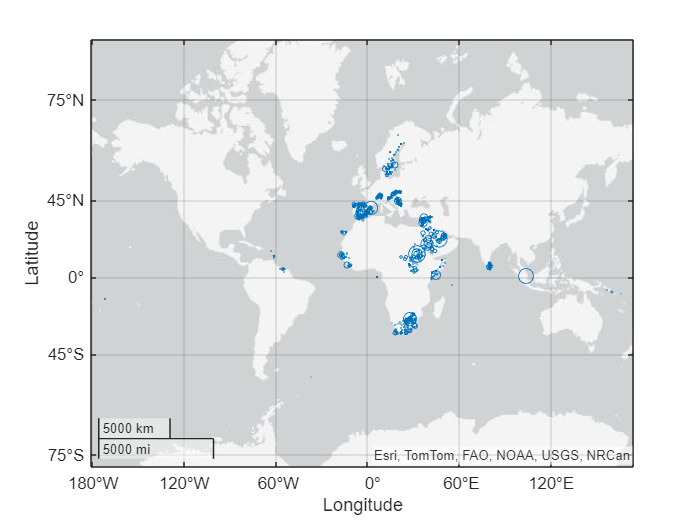

%My name is Ahnaf Sakif. First letter is S

countries = char(worldcities.country);
S_countries = worldcities(countries(:,1) == 'S', :);
normalized_popul = (S_countries.population/(max(S_countries.population) - min(S_countries.population)))*100;
geoscatter(S_countries.lat, S_countries.lng, normalized_popul);

**Exercise - 07**

% Case - 01
clc
clear all
x = [1,2; 2,1];
z = sort(x, 2);
[a,b] = unique(z, 'rows');
x(b,:)

ans =      1     2



% Case - 02
x = [1,2; 2,1; 2,1];
z = sort(x, 2);
[a,b] = unique(z, 'rows');
x(b,:)

ans =      1     2



% Case - 03
x = [1,2; 2,1; 1,2; 2,1];
z = sort(x, 2);
[a,b] = unique(z, 'rows');
x(b,:)

ans =      1     2



% Case - 04
x = [1,2; 2,1; 3,2; 4,3; 1,2; 2,1; 2,1; 3,4];
z = sort(x, 2);
[a,b] = unique(z, 'rows');
x(b,:)

ans =      1     2
     3     2
     4     3


**Exercise - 08**

% Case - 01
clc
clear all
a = [1, 1, 1, 1, 1, 2, 3];
b = [2, 3, 0, 0, 9, 5, 4, 1];
z = zeros(length(b)+1, length(a)+1);
for i = 2:(length(b)+1)
    for j = 2:(length(a)+1)
        if b(i-1) == a(j-1)
            z(i, j) = z(i-1, j-1) + 1;
        else
            z(i, j) = max(z(i-1, j), z(i, j-1));
        end
    end
end
max(z, [], 'all')

ans = 2


% Case - 02
a = [1,1,1,1,1,2,3,1,4];
b = [zeros(1,50), ones(1,200), ones(1,20)*3];
z = zeros(length(b)+1, length(a)+1);
for i = 2:(length(b)+1)
    for j = 2:(length(a)+1)
        if b(i-1) == a(j-1)
            z(i, j) = z(i-1, j-1) + 1;
        else
            z(i, j) = max(z(i-1, j), z(i, j-1));
        end
    end
end
max(z, [], 'all')

ans = 6


% Case - 03
a = 'aaabbbcccxyz';
b = 'abcyycbaabc';
z = zeros(length(b)+1, length(a)+1);
for i = 2:(length(b)+1)
    for j = 2:(length(a)+1)
        if b(i-1) == a(j-1)
            z(i, j) = z(i-1, j-1) + 1;
        else
            z(i, j) = max(z(i-1, j), z(i, j-1));
        end
    end
end
max(z, [], 'all')

ans = 5


% Case - 04
a = [1,1,1,1,1,2,3,1,4];
b = zeros(1,500);
z = zeros(length(b)+1, length(a)+1);
for i = 2:(length(b)+1)
    for j = 2:(length(a)+1)
        if b(i-1) == a(j-1)
            z(i, j) = z(i-1, j-1) + 1;
        else
            z(i, j) = max(z(i-1, j), z(i, j-1));
        end
    end
end
max(z, [], 'all')

ans = 0

**Exercise - 09**

clc
clear all
n = 5;
a = n;
j = 3;
for i = n-1:-1:0
    a = padarray(a, 1, i, 'both');
    a = [repmat(i, [j,1]) a repmat(i, [j,1])];
    j = j + 2;
end
a

a =      0     0     0     0     0     0     0     0     0     0     0
     0     1     1     1     1     1     1     1     1     1     0
     0     1     2     2     2     2     2     2     2     1     0
     0     1     2     3     3     3     3     3     2     1     0
     0     1     2     3     4     4     4     3     2     1     0
     0     1     2     3     4     5     4     3     2     1     0
     0     1     2     3     4     4     4     3     2     1     0
     0     1     2     3     3     3     3     3     2     1     0
     0     1     2     2     2     2     2     2     2     1     0
     0     1     1     1     1     1     1     1     1     1     0
